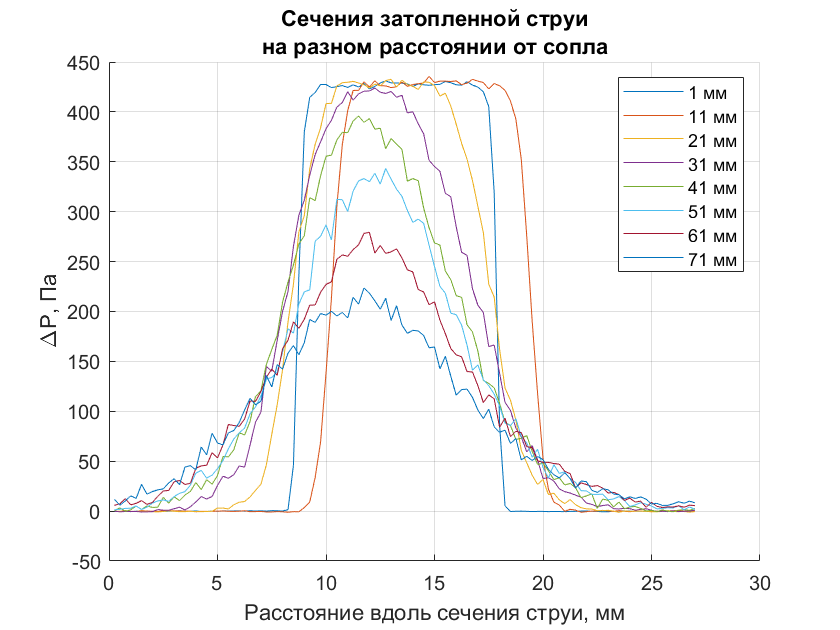


Settings = importdata("experimentData\settings.txt");
Imp01 = importdata("experimentData\01mm.dat");
Imp11 = importdata("experimentData\11mm.dat");
Imp21 = importdata("experimentData\21mm.dat");
Imp31 = importdata("experimentData\31mm.dat");
Imp41 = importdata("experimentData\41mm.dat");
Imp51 = importdata("experimentData\51mm.dat");
Imp61 = importdata("experimentData\61mm.dat");
Imp71 = importdata("experimentData\71mm.dat");
Data(:,1) = Imp01(:,2);
Data(:,2) = Imp11(:,2);
Data(:,3) = Imp21(:,2);
Data(:,4) = Imp31(:,2);
Data(:,5) = Imp41(:,2);
Data(:,6) = Imp51(:,2);
Data(:,7) = Imp61(:,2);
Data(:,8) = Imp71(:,2);
P = Data*Settings(1)+Settings(2);


%%расстояние
dx = 0.25;
x = Imp01(:,1)' * 0.25;

%%визуализация данных
hold all;
for i = 1:8
plot(x,P(:,i));
end
legend('1 мм','11 мм','21 мм','31 мм','41 мм','51 мм','61 мм','71 мм');
grid on;
xlabel("Расстояние вдоль сечения струи, мм");
ylabel("\DeltaP, Па");
title(["Сечения затопленной струи","на разном расстоянии от сопла"]);
saveas(gca,"pressure.png");
hold off;

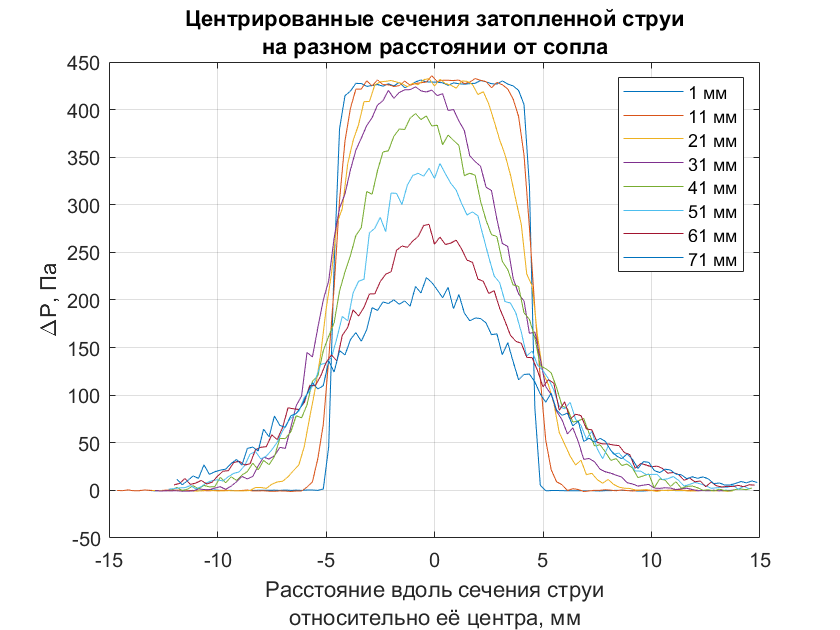


xCentered = zeros(size(P));
offset = 50;
for i = 1:8
right(i) = x(find(P(:,i)>offset, 1, 'last'));
left(i) = x(find(P(:,i)>offset, 1));
center = left(i) + (right(i) - left(i))/2;
xCentered(:, i) = x - center;
plot(xCentered(:,i),P(:,i));
hold on;
end
legend('1 мм','11 мм','21 мм','31 мм','41 мм','51 мм','61 мм','71 мм');
grid on;
xlabel(["Расстояние вдоль сечения струи","относительно её центра, мм"]);
ylabel("\DeltaP, Па");
title(["Центрированные сечения затопленной струи","на разном расстоянии от сопла"]);
saveas(gca,"centered.png");
hold off;

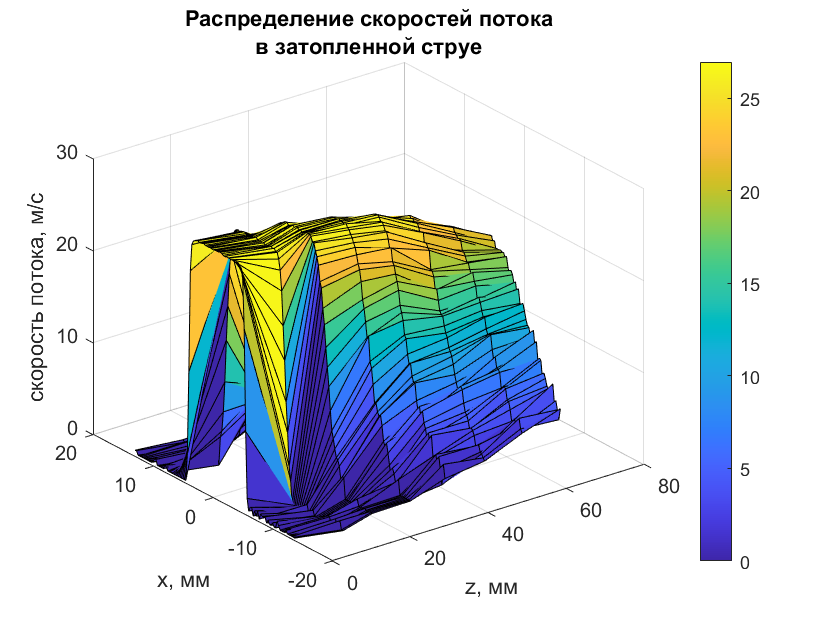


for i = 1:8
for j = 1:size(P(:,1))
if P(j,i) < 0
P(j,i) = 0;
end
end
Z(:,i) = ones(size(P(:,1)))*(10*i-9);
end
U = sqrt(10 * P / 6);
surf(Z, xCentered, U);
colorbar;
grid on;
title(["Распределение скоростей потока","в затопленной струе"]);
xlabel("z, мм");
ylabel("x, мм");
zlabel("скорость потока, м/с");
saveas(gca,"surface.png")

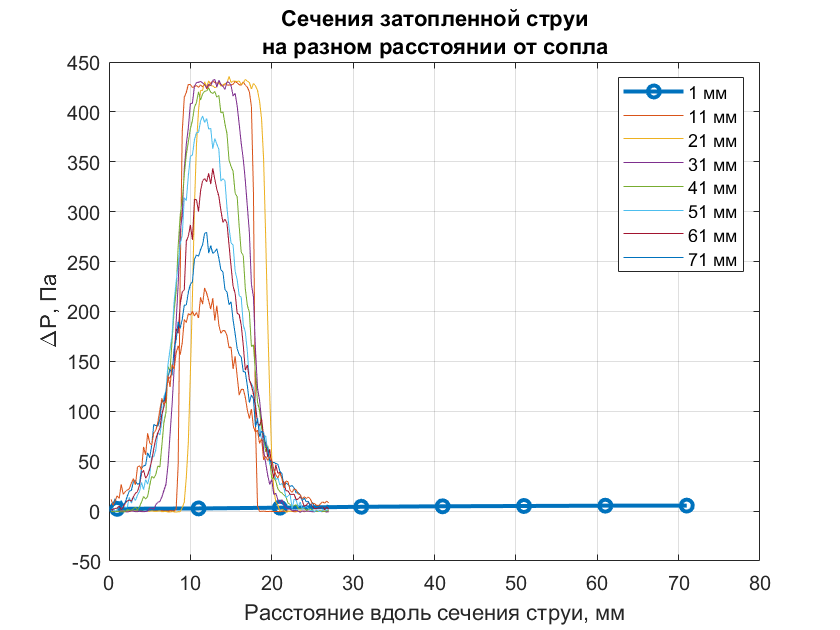


for i = 1:8
y0 = U(:,i).* abs(xCentered(:,i));
x0 = xCentered(:,i).*0.001;
Q(i) = 2*1.2*pi*trapz(x0,y0);
end
Q = Q'/2;
plot(Z(1,:),Q,'-o','LineWidth',2);
title("Расход затопленной струи");


Settings = importdata("experimentData\settings.txt");
Imp01 = importdata("experimentData\01mm.dat");
Imp11 = importdata("experimentData\11mm.dat");
Imp21 = importdata("experimentData\21mm.dat");
Imp31 = importdata("experimentData\31mm.dat");
Imp41 = importdata("experimentData\41mm.dat");
Imp51 = importdata("experimentData\51mm.dat");
Imp61 = importdata("experimentData\61mm.dat");
Imp71 = importdata("experimentData\71mm.dat");
Data(:,1) = Imp01(:,2);
Data(:,2) = Imp11(:,2);
Data(:,3) = Imp21(:,2);
Data(:,4) = Imp31(:,2);
Data(:,5) = Imp41(:,2);
Data(:,6) = Imp51(:,2);
Data(:,7) = Imp61(:,2);
Data(:,8) = Imp71(:,2);
P = Data*Settings(1)+Settings(2);


%%расстояние
dx = 0.25;
x = Imp01(:,1)' * 0.25;

%%визуализация данных
hold all;
for i = 1:8
plot(x,P(:,i));
end
legend('1 мм','11 мм','21 мм','31 мм','41 мм','51 мм','61 мм','71 мм');
grid on;
xlabel("Расстояние вдоль сечения струи, мм");
ylabel("\DeltaP, Па");
title(["Сечения затопленной струи","на разном расстоянии от сопла"]);
saveas(gca,"pressure.png");
hold off;


xCentered = zeros(size(P));
offset = 50;
for i = 1:8
right(i) = x(find(P(:,i)>offset, 1, 'last'));
left(i) = x(find(P(:,i)>offset, 1));
center = left(i) + (right(i) - left(i))/2;
xCentered(:, i) = x - center;
plot(xCentered(:,i),P(:,i));
hold on;
end
legend('1 мм','11 мм','21 мм','31 мм','41 мм','51 мм','61 мм','71 мм');
grid on;
xlabel(["Расстояние вдоль сечения струи","относительно её центра, мм"]);
ylabel("\DeltaP, Па");
title(["Центрированные сечения затопленной струи","на разном расстоянии от сопла"]);
saveas(gca,"centered.png");
hold off;


for i = 1:8
for j = 1:size(P(:,1))
if P(j,i) < 0
P(j,i) = 0;
end
end
Z(:,i) = ones(size(P(:,1)))*(10*i-9);
end
U = sqrt(10 * P / 6);
surf(Z, xCentered, U);
colorbar;
grid on;
title(["Распределение скоростей потока","в затопленной струе"]);
xlabel("z, мм");
ylabel("x, мм");
zlabel("скорость потока, м/с");
saveas(gca,"surface.png");

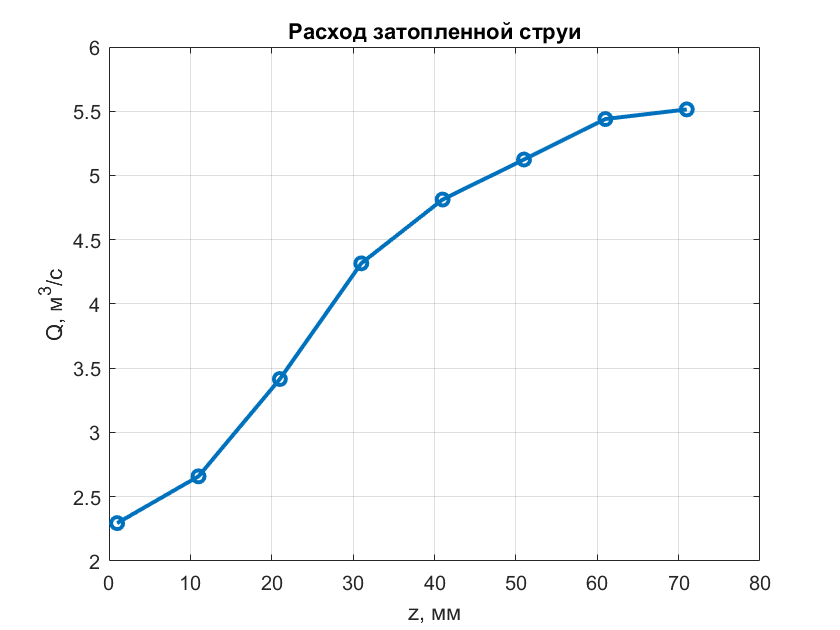


for i = 1:8
y0 = U(:,i).* abs(xCentered(:,i));
x0 = xCentered(:,i).*0.001;
Q(i) = 2*1.2*pi*trapz(x0,y0);
end
Q = Q'/2;
plot(Z(1,:),Q,'-o','LineWidth',2);
grid on;
title("Расход затопленной струи");
xlabel("z, мм");
ylabel("Q, м^3/с");
saveas(gca,"flow.png");

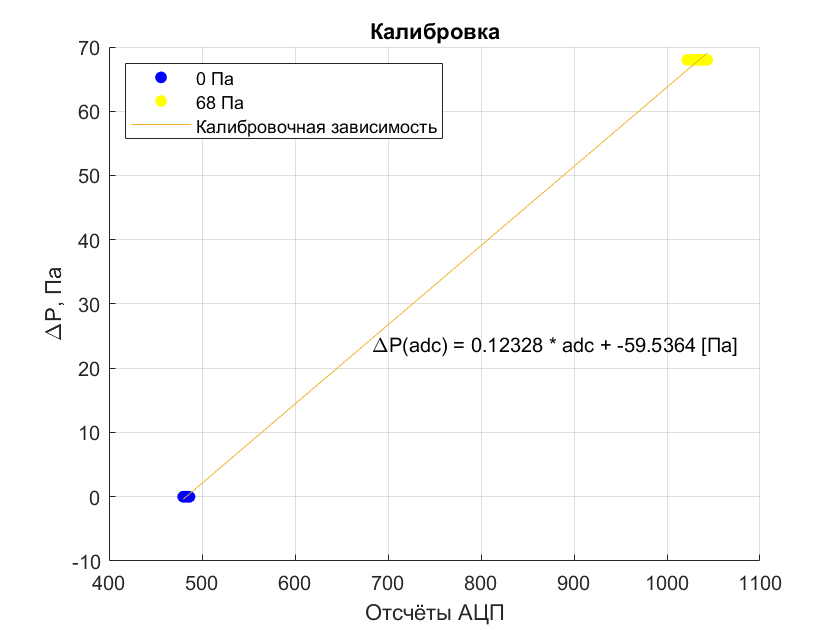

Imp0 = importdata("experimentData\calibzero.dat");
Imp68 = importdata("experimentData\calib.dat");

Adc0 = Imp0(:,2);
Adc68 = Imp68(:,2);
P0 = ones(length(Adc0),1)*0;
P68 = ones(length(Adc68),1)*68;

Adc = [Adc0; Adc68];
P = [P0; P68];

c = polyfit(Adc, P, 1);
cFigure = figure('Name','Calibration','NumberTitle','off');
hold all;

plot(Adc0,P0,'.','MarkerSize', 20,'Color',[0,0,1]);
plot(Adc68,P68,'.','MarkerSize', 20,'Color',[1,1,0]);
plot(Adc,polyval(c,Adc));

legend('0 Па','68 Па','Калибровочная зависимость','Location','NorthWest');
grid on;
xlabel('Отсчёты АЦП');
ylabel('\DeltaP, Па');
title('Калибровка');
text(mean(Adc)*0.9,mean(P)*0.7,['\DeltaP(adc) = ', num2str(c(1)),' * adc + ',num2str(c(2)),' [Па]']);

settings = fopen('settings.txt','w');
fprintf(settings,'%f\n',c(1), c(2));
fclose(settings);

saveas(cFigure, 'CalibrationGraph.png');